# Linearized Kalman Filter

% Bringing in required functions and variables 
% bringing in simulation data and provided data
load sim_setup.mat
load orbitdetermination-finalproj_data_2023_11_14.mat
addpath('./functions/')

## Useful Constants

m = length(a_SRP);  % number of inputs equals the length of this vector
p = 2;              % number of measurement variables

% chosen step size
% dt = dt_int;
dt = dt_obs;

% non-linear simualtion
x_pert = [1e-5,1e-5,1e-5,1e-7,1e-7,1e-7]';

## Non-Linear Simulation

This is using the smaller step size 

x_0 = [r_nom; dr_nom];
options = odeset('RelTol',1e-12);
t_obs = unique(y_table(:, 1));          % times of observations [s]
t_ode45 = 0:dt:max(t_obs);
[t,x_ode45] = ode45(@(t_in,x_in) orbit(t_in,x_in,a_SRP,mu_A), t_ode45, x_0, options);
[steps,n] = size(x_ode45);

## Linearized System Matrices

% CT B matrix
B = zeros(n,m);
B(4:end,:) = eye(3);
u = a_SRP;

% CT Gamma matrix 
Gamma = zeros(n,m);
Gamma(4:end,:) = eye(3);

% CT Noise matrices
W = eye(m)*sig_w^2;
V = eye(p)*sig_v^2;
R = V/dt;

% creating useful vectors for all times 
dx_plus = zeros(steps,n);
dx_minus = zeros(steps,n); 
X_plus = zeros(steps,n); 
P_plus = zeros(n,n,steps);

% number of landmarks to use
num_marks = 50
lps = pos_lmks_A(:,1:num_marks);

% initializing these vectors 
dx_plus(1,:) = x_pert';
X_plus(1,:) =  x_ode45(1,:) + x_pert';
P_plus(:,:,1) = diag([ones(1,3),ones(1,3)*1e-1])*1e-2;

num_marks = 50

for k = 2:steps
    % time for this time step
    t_k = t(k);

    % calculating nominal state
    x_nom_k = x_ode45(k,:)';
    
    % Jacobians for nominal state
    A = dfdx(x_nom_k,mu_A);

    % Putting this in the discrete time 
    [F,G,Q] = state_CT_to_DT(dt,A,B,Gamma,W);

    % obtaining the H matrix
    RNC = R_CtoN(:, :, k);
    H = zeros(p*num_marks,n);
    dy = zeros(p*num_marks,1);
    R_k = kron(eye(num_marks),R);
    for i = 1:num_marks
        lp = lps(:,i); % landmark i

        % obtaining H matrix for this landmark at this time
        H_i = H_k(lp,x_nom_k,t_k,RNC);
        rows = (p*(i-1)+1):(p*i);
        H(rows,:) = H_i;
        
        % observation difference matrix
        dy_i =  y_measured(lp, x_nom_k, RNC, t_k,true,false) - y_measured(lp, x_nom_k, RNC, t_k,false,false);
        dy(rows) = dy_i;
    end

    % prediction step
    dx_minus = F*dx_plus(k-1,:)' + G*u;
    P_minus = F*P_plus(:,:,k-1)*F' + Q;
    K = P_minus * H' * inv(H * P_minus * H' + R_k);

    % correction step
    dx_plus_k = dx_minus + K*(dy - H*dx_minus);
    P_plus_k = (eye(n) - K*H)*P_minus;

    % saving this
    dx_plus(k,:) = dx_plus_k';
    P_plus(:,:,k) = P_plus_k;
    X_plus(k,:) = x_nom_k + dx_plus_k;
end

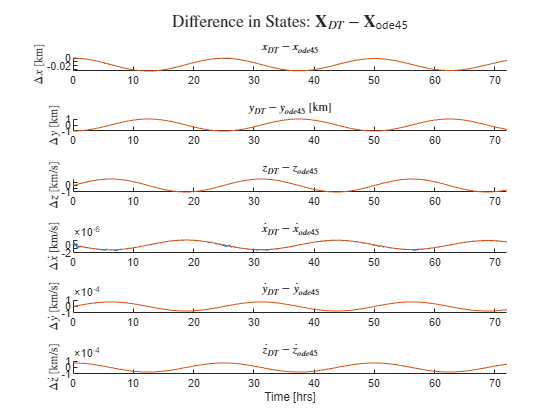


figure;
fig = tiledlayout(n,1);
titles =   ["$x_{DT} - x_{ode45}$", "$y_{DT} - y_{ode45}$ [km]","$z_{DT} - z_{ode45}$", ...
            "$\dot x_{DT} - \dot x_{ode45}$", "$\dot y_{DT} - \dot y_{ode45}$","$\dot z_{DT} - \dot z_{ode45}$"];
ylabels =   ["$\Delta x$ [km]", "$\Delta y$ [km]","$\Delta z$ [km/s]", ...
            "$\Delta \dot x$ [km/s]", "$\Delta \dot y$ [km/s]","$\Delta \dot z$ [km/s]"];
for i = 1:n
    nexttile(fig)
    hold on
    % plot(t/60/60,X_plus(:,i)-x_ode45(:,i))
    plot(t/60/60,X_plus(:,i))
    plot(t/60/60,x_ode45(:,i))
    hold off
    xlim([t(1)/60/60, 72])
    title(titles(i),Interpreter='latex')
    ylabel(ylabels(i),Interpreter='latex')
end
xlabel("Time [hrs]")
title(fig,"Difference in States: $\textbf{X}_{DT} - \textbf{X}_{\texttt{ode45}} $", Interpreter='latex')